# **Práctica 2: Primeras aplicaciones**

## **Ejercicio 1. Deteccion de discontinuidades.**

#### **1. Generar la siguiente señal y representarla**

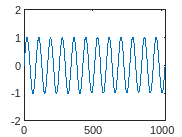

x=linspace(0,1,1024);
s=sin(24*pi*x).*(x<0.4)+(0.01+sin(24*pi*x)).*(x>0.4);
plot(s); axis([0 length(s) -2 2]);

#### 2. En primer lugar, realizar el ejercicio desde el Wavelet Analyzer, importando la señal s desde el espacio de trabajo, realizando la transformada wavelet y analizando los coeficientes de fluctuaci´on experimentando con diferentes tipos de wavelets y niveles de descomposici´on.

% waveletSignalAnalyzer

#### 3. Usando la wavelet ’haar’, calcular la transformada wavelet de la señal s de nivel 3.

% Calcular la transformada wavelet de nivel 3 usando la wavelet 'haar'
[coef, L] = wavedec(s, 3, 'haar');

% Mostrar los coeficientes de la wavelet
disp(coef);

    0.7113    2.0903    2.7634    2.5033    1.3978   -0.1797   -1.6965   -2.6405   -2.6927   -1.8356   -0.3586    1.2395    2.4190    2.7816    2.2049    0.8836   -0.7361   -2.1072   -2.7667   -2.4919   -1.3756    0.2053    1.7169    2.6486    2.6859    1.8162    0.3331   -1.2624   -2.4317   -2.7797   -2.1891   -0.8592    0.7609    2.1240    2.7698    2.4803    1.3532   -0.2309   -1.7370   -2.6565   -2.6789   -1.7966   -0.3076    1.2853    2.4441    2.7776    2.1731    0.8347   -0.7855   -2.1405   -2.7726   -2.4472   -1.3023    0.2848    1.7853    2.6925    2.7000    1.8052    0.3104   -1.2797   -2.4281   -2.7469   -2.1286   -0.7819    0.8384    2.1852    2.8035    2.4847    1.3363   -0.2538   -1.7486   -2.6434   -2.6359   -1.7288   -0.2282    1.3589    2.4967    2.8009    2.1688    0.8138   -0.8064   -2.1448   -2.7493   -2.4158   -1.2570    0.3359    1.8249    2.7072    2.6848    1.7653    0.2592   -1.3249   -2.4520   -2.7415   -2.0957   -0.7326    0.8875    2.2174    2.8080    2.4599

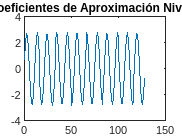


% Graficar los coeficientes de aproximación en el nivel 3
aprox = appcoef(coef, L, 'haar', 3);
figure;
plot(aprox);
title('Coeficientes de Aproximación Nivel 3');

#### 4. Extraer los coeficientes (detcoef) de fluctuaci´on (detalle) de niveles 1, 2 y 3 y representarlos gr´aficamente y localizar la discontinuidad.

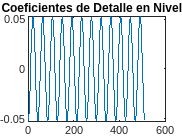

% Suponiendo que 'coeffs' y 'L' se obtuvieron de la operación wavedec anterior
% Extraer coeficientes de detalle para los niveles 1, 2 y 3
[D1, D2, D3] = detcoef(coef, L, [1 2 3]);

% Graficar coeficientes de detalle para el nivel 1
figure;
plot(D1);
title('Coeficientes de Detalle en Nivel 1');

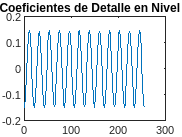


% Graficar coeficientes de detalle para el nivel 2
figure;
plot(D2);
title('Coeficientes de Detalle en Nivel 2');

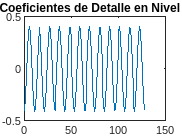


% Graficar coeficientes de detalle para el nivel 3
figure;
plot(D3);
title('Coeficientes de Detalle en Nivel 3');


% Para localizar la discontinuidad, observa los picos en los coeficientes de detalle

#### 5. Repetir el ejercicio para distintas wavelets: ’db2’, ’db3’ y ’coif2’.

**bd2**

    0.0780    0.0662    1.3016    2.4769    2.8156    2.2036    0.8474   -0.7950   -2.1689   -2.8104   -2.5028   -1.3500    0.2587    1.7800    2.7002    2.7085    1.8022    0.2873   -1.3247   -2.4893   -2.8133   -2.1872   -0.8225    0.8199    2.1855    2.8130    2.4906    1.3271   -0.2846   -1.8001   -2.7078   -2.7010   -1.7821   -0.2614    1.3476    2.5015    2.8106    2.1706    0.7976   -0.8448   -2.2019   -2.8154   -2.4781   -1.3040    0.3105    1.8201    2.7151    2.6932    1.7618    0.2354   -1.3705   -2.5138   -2.8042   -2.1256   -0.7443    0.8979    2.2464    2.8459    2.4938    1.3091   -0.3081   -1.8117   -2.6940   -2.6569   -1.7131   -0.1812    1.4215    2.5536    2.8330    2.1652    0.7758   -0.8661   -2.2059   -2.7912   -2.4244   -1.2293    0.3905    1.8880    2.7574    2.7052    1.7491    0.2118   -1.3875   -2.5086   -2.7731   -2.0915   -0.6940    0.9473    2.2783    2.8495    2.4679    1.2625   -0.3597   -1.8509   -2.7075   -2.6402   -1.6718   -0.1292    1.4665    2.5766

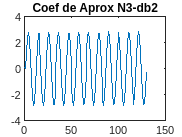

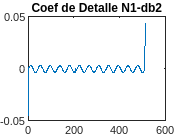

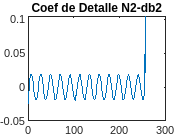

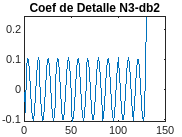

detecDiscon(s,"db2")

**db3**

    0.2916    0.2176    0.2292    0.4652    1.8651    2.7324    2.6770    1.7175    0.1780   -1.4216   -2.5411   -2.8025   -2.1175   -0.7174    0.9249    2.2550    2.8235    2.4385    1.2300   -0.3938   -1.8847   -2.7391   -2.6685   -1.6968   -0.1520    1.4440    2.5524    2.7989    2.1002    0.6922   -0.9495   -2.2706   -2.8249   -2.4252   -1.2065    0.4196    1.9040    2.7454    2.6597    1.6758    0.1260   -1.4664   -2.5636   -2.7950   -2.0826   -0.6669    0.9740    2.2860    2.8260    2.4117    1.1829   -0.4453   -1.9225   -2.7553   -2.6328   -1.6265   -0.0717    1.5169    2.6027    2.8192    2.0932    0.6698   -0.9702   -2.2730   -2.7987   -2.3697   -1.1309    0.4993    1.9705    2.7858    2.6698    1.6619    0.1022   -1.4824   -2.5569   -2.7583   -2.0187   -0.5879    1.0511    2.3446    2.8559    2.4123    1.1637   -0.4684   -1.9328   -2.7349   -2.6039   -1.5839   -0.0196    1.5609    2.6239    2.8103    2.0572    0.6190   -1.0188   -2.3029   -2.7998   -2.3416   -1.0832    0.5506

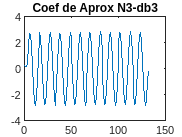

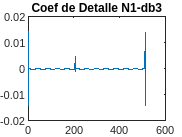

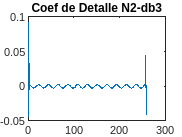

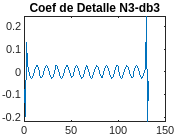

detecDiscon(s,"db3")

**coif2**

    0.3923    0.7572    0.3693    0.6334    0.6115    0.3670    1.1387    2.4352    2.8249    2.2683    0.9458   -0.6962   -2.1030   -2.7996   -2.5508   -1.4406    0.1561    1.7001    2.6699    2.7382    1.8817    0.3898   -1.2337   -2.4407   -2.8234   -2.2526   -0.9212    0.7214    2.1203    2.8032    2.5394    1.4181   -0.1821   -1.7208   -2.6784   -2.7315   -1.8622   -0.3640    1.2571    2.4537    2.8217    2.2368    0.8965   -0.7465   -2.1375   -2.8065   -2.5279   -1.3955    0.2081    1.7414    2.6867    2.7247    1.8425    0.3381   -1.2805   -2.4666   -2.8177   -2.1926   -0.8436    0.7999    2.1827    2.8379    2.5444    1.4011   -0.2058   -1.7336   -2.6664   -2.6893   -1.7944   -0.2840    1.3319    2.5075    2.8459    2.2328    0.8752   -0.7684   -2.1429   -2.7843   -2.4758   -1.3217    0.2883    1.8105    2.7308    2.7385    1.8309    0.3146   -1.2984   -2.4634   -2.7869   -2.1598   -0.7937    0.8499    2.2161    2.8435    2.5201    1.3553   -0.2577   -1.7741   -2.6818   -2.6743

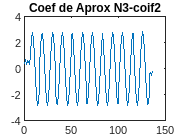

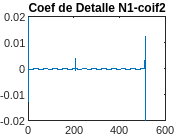

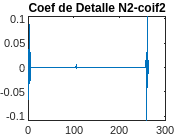

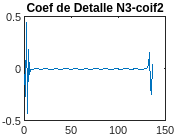

detecDiscon(s,"coif2")

#### 5. Pensar en c´omo localizar la discontinuidad de forma autom´atica, sin necesidad de visualizar las gr´aficas.

hallarDisc(s,'coif2',0.01)

ans =      2     3   514   515


## Ejercicio 2: Discontinuidad en derivadas

#### 1. Cargar la señal ’nearbrk.mat’, ejemplo ”Two nearby discontinuities”, y representarla.

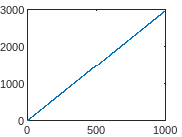

load("nearbrk.mat")
s=nearbrk;
figure; plot(s)

#### 2. Realizar una descomposici´on wavelet para diferentes waveletes (con distinto n´umero de momentos nulos), por ejemplo: ’haar’, ’db2’, ’db3’ y ’coif2’ y niveles, elegir por ejemplo nivel 3.

#### 3. Extraer (con detcoef) y representar los coeficientes de fluctuaci´on de los distintos niveles y localizar las discontinuidades.

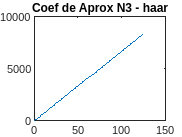

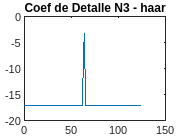

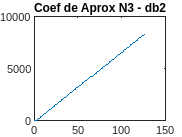

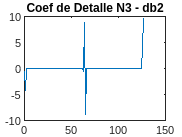

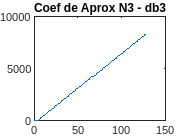

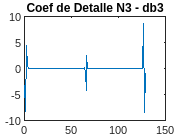

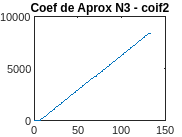

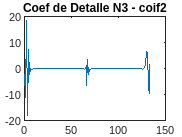

% Lista de wavelets para la descomposición
wavelets = {'haar', 'db2', 'db3', 'coif2'};
nivel = 3;

% Realizar la descomposición wavelet para cada wavelet y nivel especificado
for i = 1:length(wavelets)
    [C, L] = wavedec(s, nivel, wavelets{i});
    
    % Obtener y graficar los coeficientes de aproximación del nivel 3
    A = appcoef(C, L, wavelets{i}, nivel);
    figure;
    plot(A);
    title(['Coef de Aprox N3 - ' wavelets{i}]);
    
    % Obtener y graficar los coeficientes de detalle del nivel 3
    D = detcoef(C, L, nivel);
    figure;
    plot(D);
    title(['Coef de Detalle N3 - ' wavelets{i}]);
end

#### 4. Obtener las conclusiones relacionando los momentos nulos de la wavelet con la discontinuidad de la derivada.

## Ejercicio 3: Discontinuidad en derivadas

#### **1. Cargar la señal ’scddvbrk.mat’, corresponde al ejemplo ”Second derivative breakdown”, y representarla.**

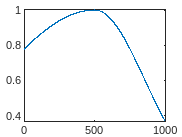

load("scddvbrk.mat")
s=scddvbrk;
figure; plot(s)

#### 2. Repetir para esta señal todos los pasos del ejercicio anterior, usando adem´as la ’db4’.

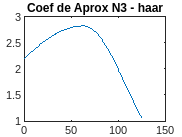

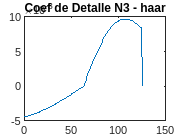

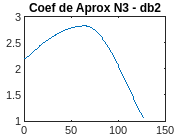

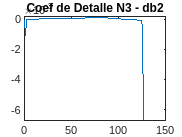

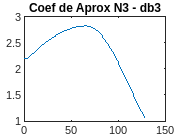

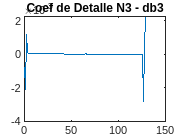

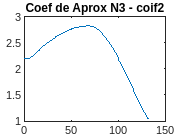

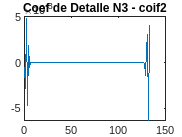

% Lista de wavelets para la descomposición
wavelets = {'haar', 'db2', 'db3', 'coif2', 'db4'};
nivel = 3;

% Realizar la descomposición wavelet para cada wavelet y nivel especificado
for i = 1:length(wavelets)
    [C, L] = wavedec(s, nivel, wavelets{i});
    
    % Obtener y graficar los coeficientes de aproximación del nivel 3
    A = appcoef(C, L, wavelets{i}, nivel);
    figure;
    plot(A);
    title(['Coef de Aprox N3 - ' wavelets{i}]);
    
    % Obtener y graficar los coeficientes de detalle del nivel 3
    D = detcoef(C, L, nivel);
    figure;
    plot(D);
    title(['Coef de Detalle N3 - ' wavelets{i}]);
end

#### 3. Observar las diferencias entre lo que ocurre con los coeficientes de fluctuaci´on si utilizamos la wavelet haar o la db2 y lo que sucede al utilizar la ’db4’. Obtener conclusiones teniendo en cuenta los momentos nulos del tipo de wavelet utilizada.

## Ejercicio 4: Un cambio de frecuencia.

#### 1. Cargar la señal ’freqbrk.mat’, ejemplo ”Frequency breakdown”, y representarla. 

#### 2. Calcular la transformada wavelet de nivel 6, usando distintas wavelet (con ’haar’, ’db2’...).

#### 3. Localizar el instante de la variaci´on de frecuencia. Para ello calculamos la transformada wavelet (con ’haar’, ’db2’...), extraemos (detcoef) los coeficientes de fluctuaci´on de nivel 1 y localizamos el m´aximo (ojo a los efectos de bordes). Gr´aficamente representamos los coeficientes.

#### 4. Con ’wrcoef’, obtener las se˜nales reconstruidas de promedio A1, A2,..., A6 y de detalle D1, D2,..., D6 y representarlas todas juntas con subplot (en una columna A’ y en otra columna D’s). Observar como la trasformada act´ua como un filtro de frecuencias.

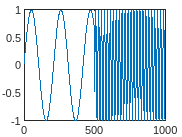

load("freqbrk.mat")
figure; plot(freqbrk)

**Haar**

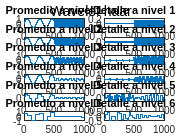

cambioFreq(freqbrk,'haar')

**db2**

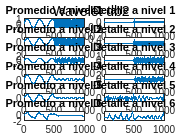

cambioFreq(freqbrk,'db2')

**db3**

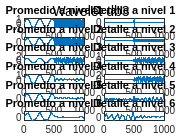

cambioFreq(freqbrk,'db3')

**coif2**

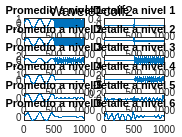

cambioFreq(freqbrk,'coif2')

**db4**

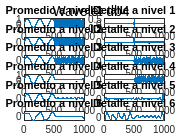

cambioFreq(freqbrk,'db4')

## Ejercicio 5: . Evoluci´on a largo tiempo

#### Cargar y representar la señal wnoislop.mat, ejemplo “Ramp + white noise”.

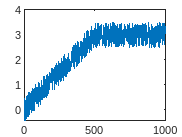

load("wnoislop.mat")
figure; plot(wnoislop)

#### Calcular la transformada wavelet de nivel 6, usando distintas wavelet (con ’haar’, ’db2’...). 

#### Con ’wrcoef’, obtener las señales reconstruidas de promedio A1, A2,..., A6 y de detalle D1, D2,..., D6 y representarlas todas juntas con subplot, como en ejercicio anterior. 

#### Analizar las señales promedio, A1, A2... para identificar la evoluci´on a largo plazo.

**Haar**

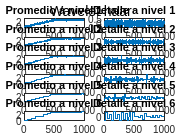

cambioFreq(wnoislop,'haar')

**db2**

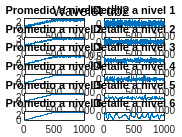

cambioFreq(wnoislop,'db2')

**db3**

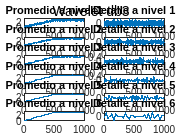

cambioFreq(wnoislop,'db3')

**coif2**

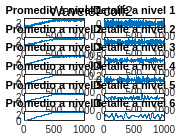

cambioFreq(wnoislop,'coif2')

**db4**

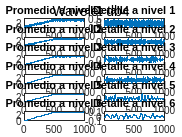

cambioFreq(wnoislop,'db4')

#### Repetir este ejercicio con la señal trsin.mat, ejemplo “Triangle + sin”.

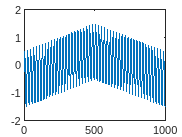

load("trsin.mat")
figure; plot(trsin)

**Haar**

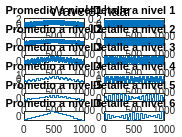

cambioFreq(trsin,'haar')

**db2**

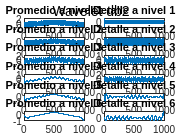

cambioFreq(trsin,'db2')

**db3**

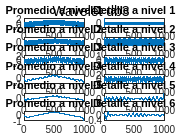

cambioFreq(trsin,'db3')

**coif2**

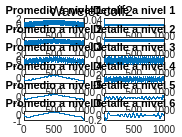

cambioFreq(trsin,'coif2')

**db4**

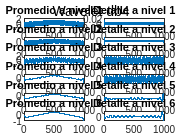

cambioFreq(trsin,'db4')

## Ejercicio 6: Identificando frecuencias puras

#### **1. Cargar y representar la señal sumsin.mat, corresponde al ejemplo “Sum of sines”. **

#### **2. Calcular la transformada wavelet de nivel 6, usando distintas wavelet (con ’haar’, ’db2’, ’coif3’,...). **

#### **3. Con ’wrcoef’, obtener las señales reconstruidas de promedio A1, A2,..., A6 y de detalle D1, D2,..., D6 y representarlas todas juntas con subplot, como en ejercicio anterior. **

#### **4 Obtener las conclusiones posibles en lo que se refiere a la descomposici´on de la señal en suma de sinusoides de diferentes frecuencias.**

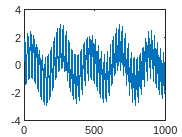

load("sumsin.mat")
figure; plot(sumsin)

**Haar**

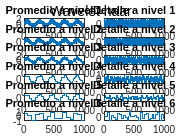

cambioFreq(sumsin,'haar')

**db2**

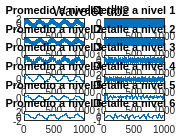

cambioFreq(sumsin,'db2')

**db3**

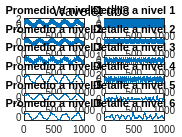

cambioFreq(sumsin,'db3')

**coif2**

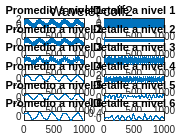

cambioFreq(sumsin,'coif2')

**db4**

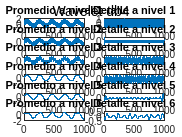

cambioFreq(sumsin,'db4')

#### 5. Observar si se filtran los distintos sinusoides en diferentes niveles de descomposici´on. Observar qu´e wavelets funcionan mejor. Probar tambi´en con la wavelet ’dmeyr’.

cambioFreq(sumsin,'dmeyr')

Error using wavemngr
Invalid wavelet name: dmeyr.

Error in wavemngr (line 339)
            case 'wn'  , i_fam = wavemngr('indw',arg);

Error in wfilters (line 63)
[wtype,fname] = wavemngr('fields',wname,'type','file');

Error in 

# Funciones

EJERCICIO 1

function detecDiscon(s, tipoWavlet)
    % Calcular la transformada wavelet de nivel 3 usando el tipo de wavelet proporcionado
    [C, L] = wavedec(s, 3, tipoWavlet);

    % Mostrar los coeficientes de la wavelet
    disp(C);

    % Graficar los coeficientes de aproximación en el nivel 3
    aprox = appcoef(C, L, tipoWavlet, 3);
    figure;
    plot(aprox);
    title(strcat('Coef de Aprox N3-', tipoWavlet));

    % Extraer y graficar coeficientes de detalle para los niveles 1, 2 y 3
    for level = 1:3
        detalleCoef = detcoef(C, L, level);
        figure;
        plot(detalleCoef);
        title(strcat('Coef de Detalle N ', num2str(level),'-', tipoWavlet));
    end
end

function [disc1, disc2, disc3] = hallarDisc(senal, tipoWavelet, umbral)
    % Descomposición wavelet hasta el nivel 3
    [coef, L] = wavedec(senal, 3, tipoWavelet);
    
    % Inicializar vectores de discontinuidades para cada nivel
    disc1 = [];
    disc2 = [];
    disc3 = [];
    
    % Evaluar cada nivel
    for nivel = 1:3
        % Obtener coeficientes de detalle para el nivel actual
        detC = detcoef(coef, L, nivel);
        
        % Identificar discontinuidades para el nivel actual
        disc = find(abs(detC) > umbral) * 2^(nivel - 1);
        
        % Almacenar discontinuidades en el vector correspondiente
        if nivel == 1
            disc1 = disc;
        elseif nivel == 2
            disc2 = disc;
        else
            disc3 = disc;
        end
    end
end

EJERCICIO 4

function cambioFreq(s, w)
    % Realizar la descomposición wavelet hasta el nivel 6
    [C, L] = wavedec(s, 6, w);
    
    % Preparar la figura para la visualización
    figure;
    
    % Bucle para extraer y graficar los coeficientes de aproximación y detalle
    for i = 1:6
        % Extracción de coeficientes de aproximación
        A = wrcoef('a', C, L, w, i);
        subplot(6, 2, 2*i-1);
        plot(A);
        title(['Promedio a nivel ' num2str(i)]);
        
        % Extracción de coeficientes de detalle
        D = wrcoef('d', C, L, w, i);
        subplot(6, 2, 2*i);
        plot(D);
        title(['Detalle a nivel ' num2str(i)]);
    end
    
    % Añadir un título general a la figura
    sgtitle(['Wavelet ' w]);
end